
% Defining the variables
clc;
syms Pdyn y w theta alphaR a b g N a1 a2 a3 a4 a5 b1 b2 b3 b4 b5
% Given Data
[Clalphac,lambda,AR,M,g,N,mass,Vs,EI,GJ,m,s,c,ec,xcg,cmac0]= deal(5.422,0.61,9.43,0.8,9.81,3,66000,316.4,2E8 ,1.75E8 ,500,17.68,3.072,0.6875,-0.1123,-0.015);
% Clalphac= Cl alpha corrected (per radian)
% lambda =  Sweep angle wrt to EA axis (radian)
% AR =  Aspect Ratio
% M =  Mach Number
% g =  Acceleration Due To Gravity
% N = Load Factor
% mass =  Mass in Kg
% s = Span(m) in y' direction i.e. Elastic Axis
% Vs = Velocity Of Sound (m/sec) at 6 Km
Pdyn = (0.5*0.66*((M*Vs)^2)); % Dynamic Pressure at 6 km
% % Properties Of Wing
% EI = Variation Of Product Of E and I with y
% GJ =  Variation Of Product Of G and J with y
% m = Variation Of Mass Of Wing With y
% c =  Variation Of Chord Length With y
% ec = Distance from EA to AC
% xcg =  Distance from EA to AC
% cmac0 = Aerodynamic Moment Co-Efficent
% % Assuming Approximate Function For 'w' And 'theta'
ai =5 %Number Of constants In The Approximate Function For w

ai = 5

bi = ai; % Number Of constants In The Approximate Function For theta
a = sym('a',[1 ai]); % Creating an array for a's parameters
a = a.'; % Converting it into a Column Vector
b = sym('b',[1 bi]); % Creating an array for b's parameters
b = b.'; % Converting it into a Column Vector
w = 0; % Initializing The Approximate Function For Deflection 'w' 
theta =0; % Initialing The Approximate Function For Theta 
for i = 1:ai
 w = a(i,1)*y^(i+1) + w;
end
for i = 1:bi
 theta = b(i,1)*y^(i) + theta;
end
% Effective Total Angle Of Attack
phi = diff(w,y); 
alphaT = alphaR + theta*cos(lambda) - phi*sin(lambda);
% Forces And Moment Relations
l = Pdyn*c*Clalphac*alphaT; % Running Lift / Unit Length 
l_ = (l - N*m*g)*cos(lambda); % Net Force Per Unit Length Of Span
my = ((l*ec) - (N*m*g*xcg))*(cos(lambda)^2) + (Pdyn*(cos(lambda)^2)*(c^2)*cmac0);
% Twisting Moment Per Unit Length Of Span
% Differentitation Terms
dw_dy = diff(w, y); 
dw2_dy2 = diff((dw_dy), y);
dtheta_dy = diff(theta, y);
% Strain Energy, Work Done And Potential Energy Functional
UB = 0.5*int((EI*((dw2_dy2)^2)),y,[0 s]); % Bending Strain Energy
UT = 0.5*int((GJ*((dtheta_dy)^2)),y,[0 s]); 
% Torsional Strain Energy
WeB = int((l_*w), y,[0 s]); % Workdone In Bending
WeT = int((my*theta), y,[0 s]); % Workdone In Twisting
PEB = vpa((UB-WeB), 4); % Bending Energy Functional 
PET = vpa((UT-WeT), 4); % Twisting Energy Functional
PEF = vpa((PEB+PET), 4); % Potential Energy Functional
% Rayleigh Ritz Method Minimizing The Potential Energy Functional
eqn = cell(ai+bi, 1); % Cell Defined For Equation
Coeff = cell(ai+bi, 1); % Cell Defined For Co-efficients
for i = 1:ai
 eqn{i} = diff(PEF, a(i)); % Differentiation wrt to ai
end
for i = 1:bi
 eqn{i+ai} = diff(PEF, b(i)); % Differentiation wrt to bi
end
for i = 1:ai+bi
 Coeff{i} = fliplr(coeffs(eqn{i}, [a b]));
end

S = solve(eqn{:});
[a1,a2,a3,a4,a5,b1,b2,b3,b4,b5]= deal(S.a1,S.a2,S.a3,S.a4,S.a5,S.b1,S.b2,S.b3,S.b4,S.b5)

$$a1 = 0.22428084861857707266252440386185\,\mathrm{alphaR}-0.0084976148687680466764004675036193$$

$$a2 = 0.00037818251199711691275116160575783-0.0099108171924795776750247991554944\,\mathrm{alphaR}$$

$$a3 = 0.000056712138841465300985715790173757\,\mathrm{alphaR}-0.0000023732296472553553958613746978395$$

$$a4 = 0.0000044416709439421123863492728578258\,\mathrm{alphaR}-0.0000001615734217049280292699432942205$$

$$a5 = 0.0000000012386465151425527029536418968256-0.000000034349490104982618216504246737423\,\mathrm{alphaR}$$

$$b1 = 0.35961958316171078948092613523491\,\mathrm{alphaR}-0.012961602773056289240704289124857$$

$$b2 = -0.00017661242509240478973533951398995\,\mathrm{alphaR}-0.0000083969377014578770208072099688737$$

$$b3 = 0.0000045492998440717203800737918497081-0.00012403383531160177647678017428238\,\mathrm{alphaR}$$

$$b4 = 0.00000072127973121240750477178127476487-0.000019054927759863469568320992508238\,\mathrm{alphaR}$$

$$b5 = 0.00000037777789572362055716593950213762\,\mathrm{alphaR}-0.000000014261049574318330537999275753747$$


% Rigid Angle Of Attact For The Given Manoeuvre
Lift = 2*int(l, [0 s]); % Lift Of Both The Wings
Lift = vpa(Lift,5);
alphaR_eqn = subs(Lift-(mass*N*g)==0);
alphaR = solve(alphaR_eqn);
alphaR = vpa(alphaR, 5);
alphaR_deg = (alphaR*180)/3.1416; % In terms of degrees
fprintf('The rigid angle of attack associated with the wing for the given manevour is alphaR = %f in deg \n', alphaR_deg);

The rigid angle of attack associated with the wing for the given manevour is alphaR = 4.978672 in deg 


% Total Lift For The Given Manoeuver
l = subs(l);
Total_Lift = 2*int(l,[0 s]);
Total_Lift = subs(Total_Lift,alphaR); 
fprintf('Total Lift = %f in N \n', Total_Lift);

Total Lift = 1942380.000000 in N 


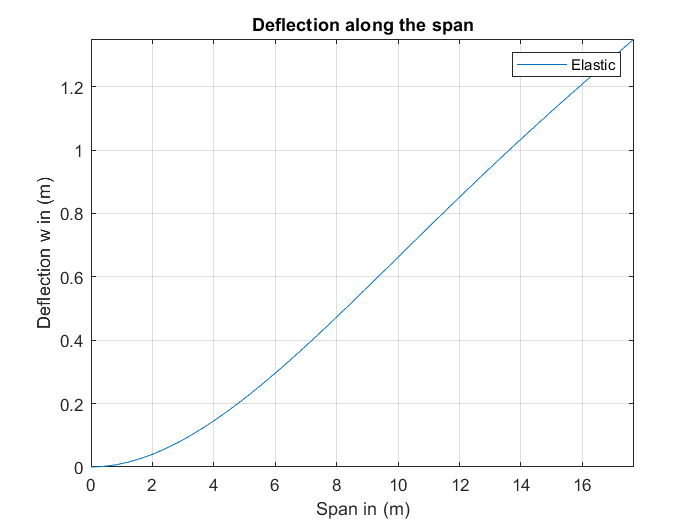

lr = Pdyn*cos(lambda)^2*c*Clalphac*alphaR;
Pzr = lr - (N*mass*g);
% Span wise distribution of w deflection
w = vpa(subs(subs(w)),4);
figure(1);
k = 0;
fplot(w,[0 s]);
legend('Elastic');
ylabel('Deflection w in (m)');
title('Deflection along the span');
xlabel('Span in (m)');
grid on;
hold off;

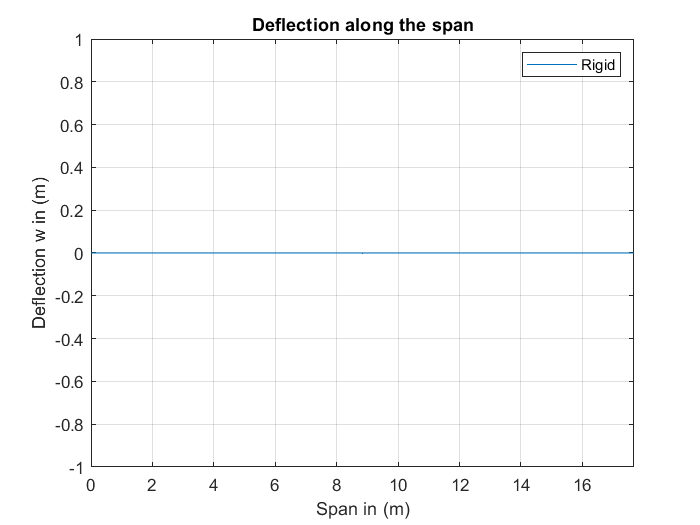

fplot(k,[0 s]);

grid on;
hold off;
legend('Rigid');
ylabel('Deflection w in (m)');
title('Deflection along the span');
xlabel('Span in (m)');

fprintf('Deflection function w = %s \n',w);

Deflection function w = 0.010991140795138287391848891321681*y^2 - 0.00048301226180345878117478009478743*y^3 + 0.000002554739119879503988886649335213*y^4 + 0.00000022438302664600840919914882996218*y^5 - 0.000000001746132720173422990463389270335*y^6 


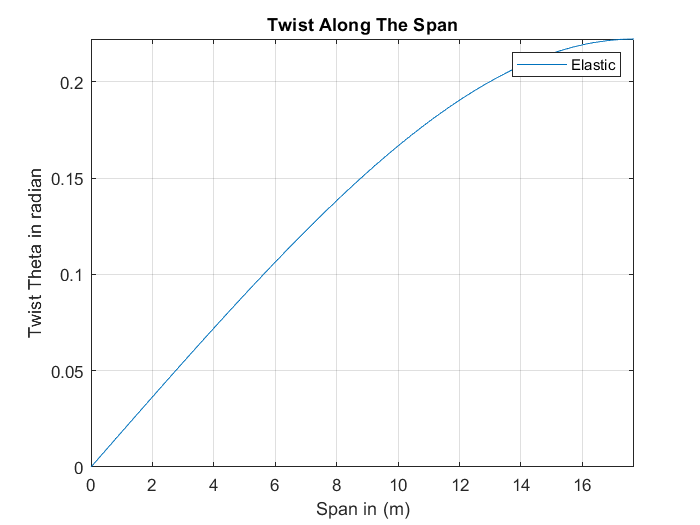

% Span Wise Distibution Of Twist Theta
theta = vpa(subs(subs(theta)), 4);
figure(2);
fplot(theta, [0 s]);
legend('Elastic');
ylabel('Twist Theta in radian');
title('Twist Along The Span');
xlabel('Span in (m)');
grid on;
hold off;

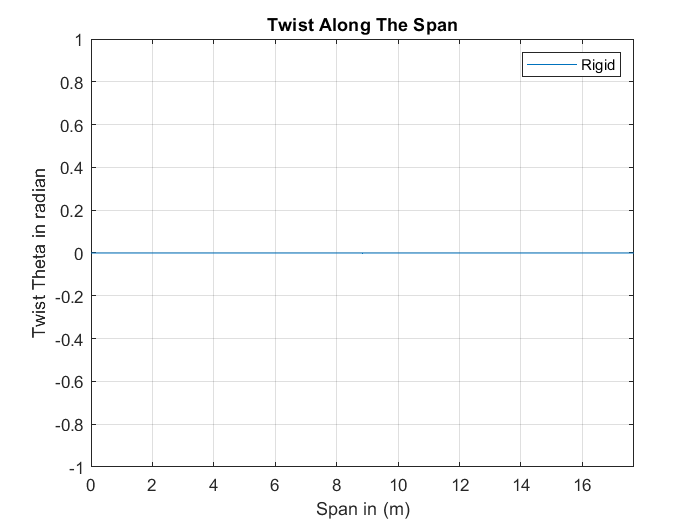

k = 0;
fplot(k, [0 s]);
grid on;

hold off;
legend( 'Rigid');
ylabel('Twist Theta in radian');
title('Twist Along The Span');
xlabel('Span in (m)');

fprintf('Twist Function Theta = %s\n', theta);

Twist Function Theta = 0.018287334580990766443750111367285*y - 0.000023743573051894755303378390877958*y^2 - 0.0000062285491133126137642915026742263*y^3 - 0.00000093448728408417151262124861563599*y^4 + 0.000000018565743931814768983435613934054*y^5


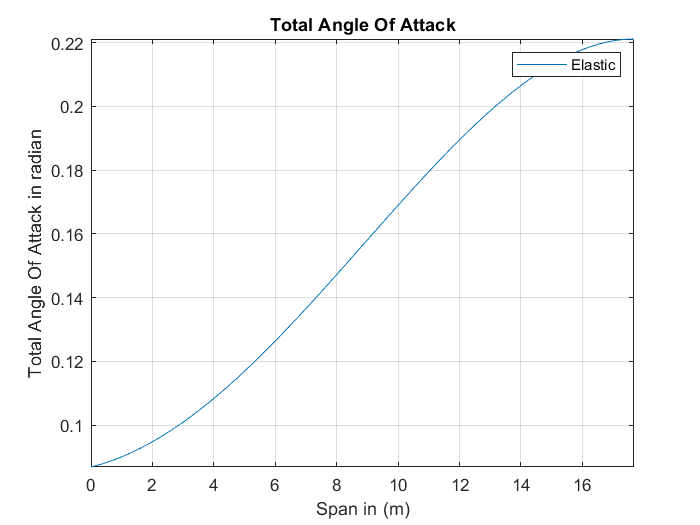

% Spanwise Distribution Of Total Angle Of Attack
alphaT = subs(alphaR+theta*cos(lambda)-(diff(w,y)*sin(lambda)));
figure(3);
fplot(alphaT, [0 s]);
legend('Elastic');
ylabel('Total Angle Of Attack in radian');
xlabel('Span in (m)');
title('Total Angle Of Attack');
grid on;
hold off;

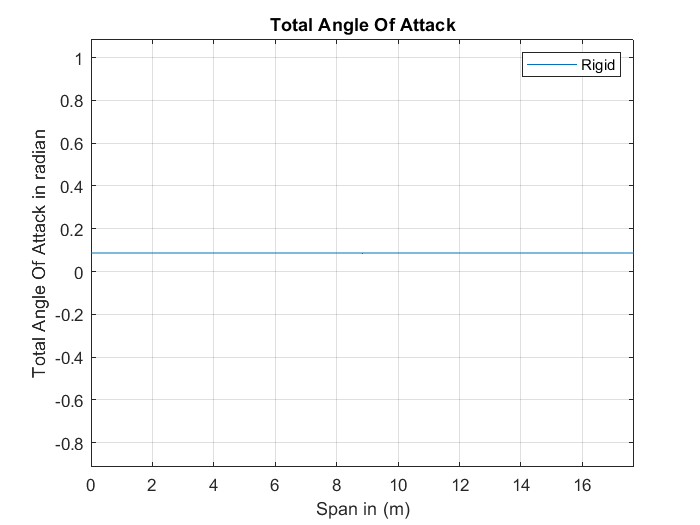

alphaTR = subs(alphaR);
fplot(alphaTR, [0 s]);
grid on;

hold off;
legend( 'Rigid');
ylabel('Total Angle Of Attack in radian');
xlabel('Span in (m)');
title('Total Angle Of Attack');

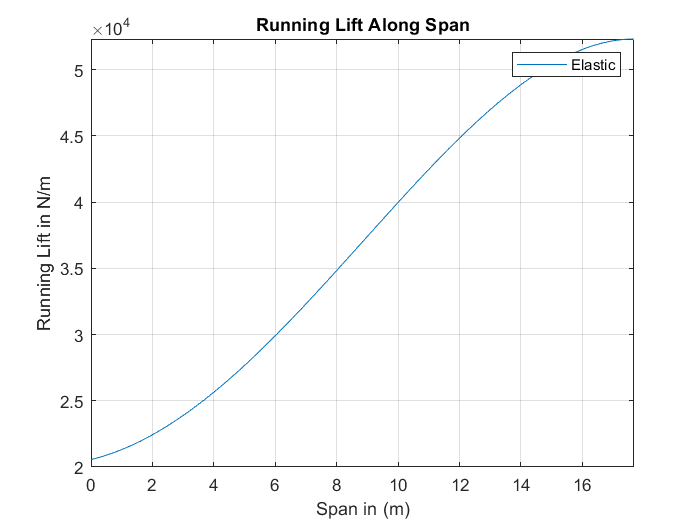

% Spanwise Distribution Of Running Lift
l = (Pdyn*(cos(lambda)^2)*c*(Clalphac)*alphaT);
figure(4);
fplot(l, [0 s]);
legend('Elastic');
ylabel('Running Lift in N/m');
xlabel('Span in (m)');
title('Running Lift Along Span');
grid on;
hold off;

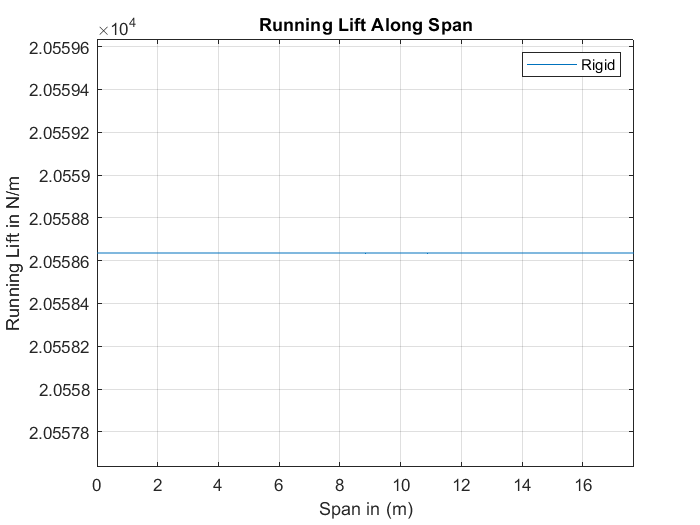

lR = (Pdyn*(cos(lambda)^2)*c*(Clalphac)*alphaTR);
fplot(lR, [0 s]);
grid on;

hold off;
legend('Rigid');
ylabel('Running Lift in N/m');
xlabel('Span in (m)');
title('Running Lift Along Span');

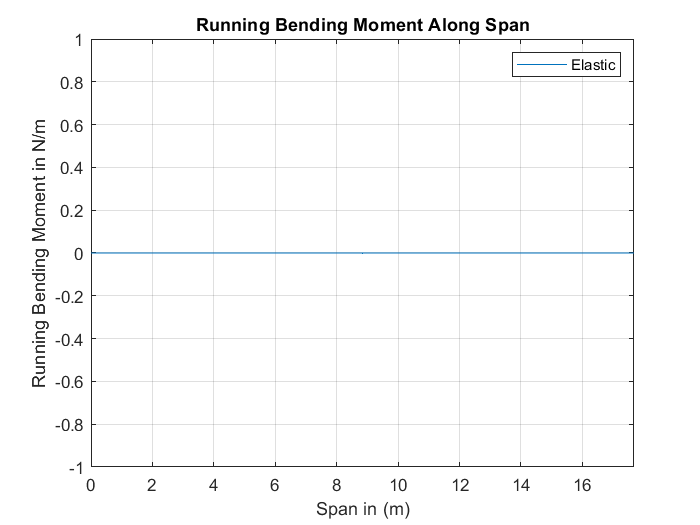

% SpanWise Distribution Of Running Bending Moment
rBM = 0;
figure(5);
fplot(rBM, [0 s]);
ylabel('Running Bending Moment in N/m');
xlabel('Span in (m)');
title('Running Bending Moment Along Span');
legend('Elastic');
grid on;
hold off;

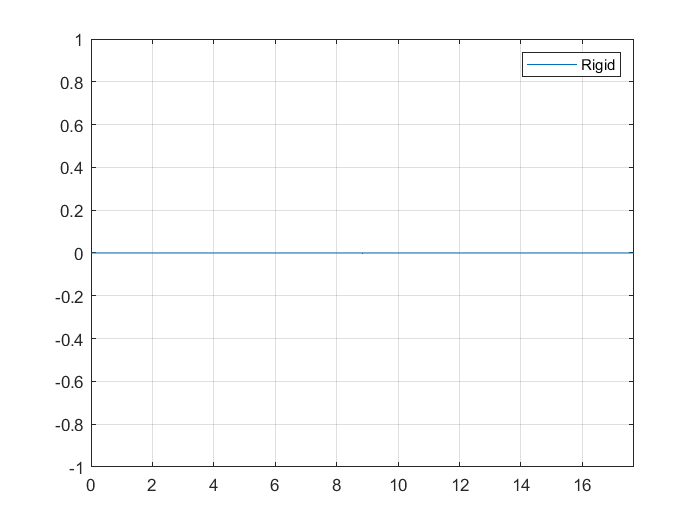

fplot(rBM, [0 s]);
grid on;
hold off;
legend('Rigid')

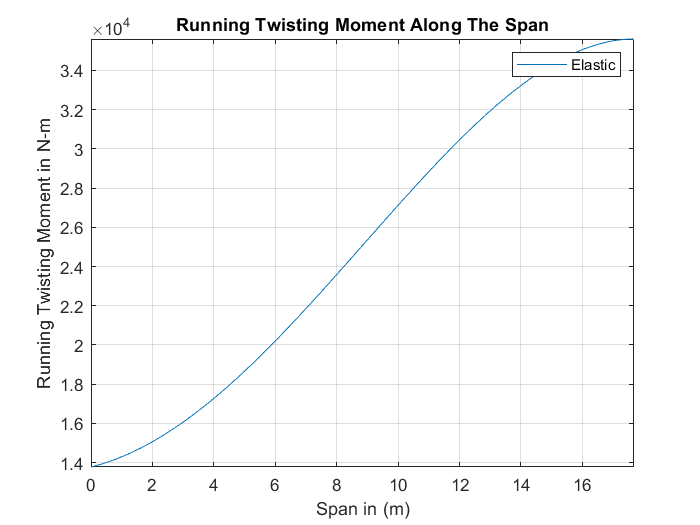

% Spanwise Distribution Of Running Twisting Moment
my = subs((l*ec) - (N*m*g*xcg) + (Pdyn*(cos(lambda)^2)*(c^2)*cmac0));
figure(6);
fplot(my, [0 s]);legend('Elastic');

ylabel('Running Twisting Moment in N-m');
xlabel('Span in (m)');
title('Running Twisting Moment Along The Span');
grid on;
hold off;

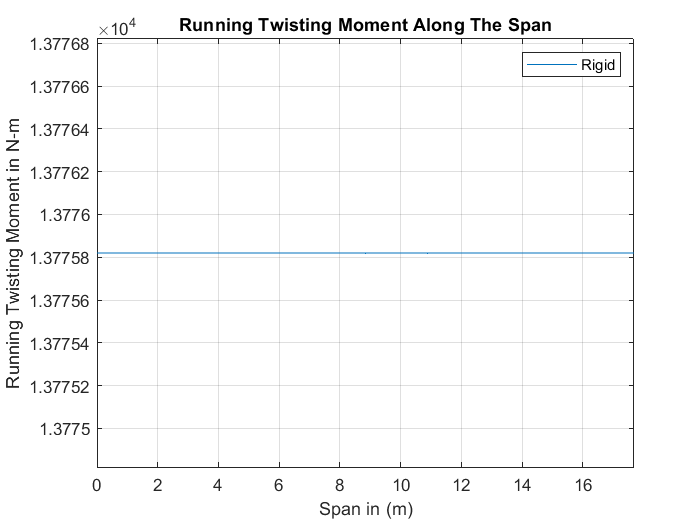

myR = subs((lR*ec) - (N*m*g*xcg) + (Pdyn*(cos(lambda)^2)*(c^2)*cmac0));
fplot(myR, [0 s]);
grid on;

hold off;
legend( 'Rigid');
ylabel('Running Twisting Moment in N-m');
xlabel('Span in (m)');
title('Running Twisting Moment Along The Span');

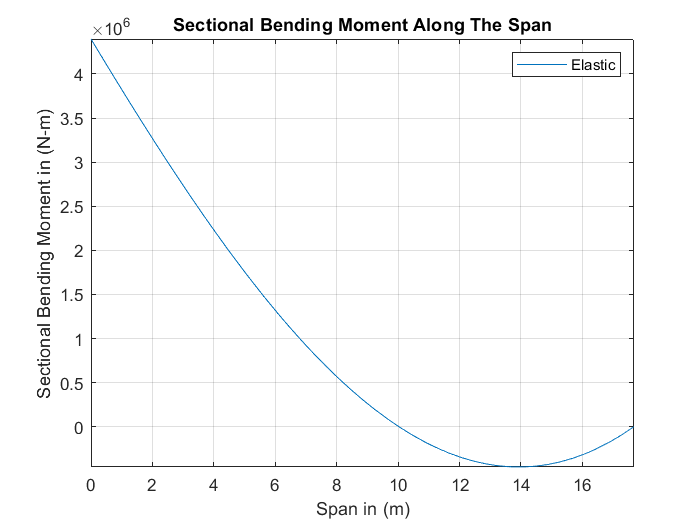

% SpanWise Distribution Of Sectional Bending Moment
dw_dy = diff(w, y);
dw2_dy2 = diff((dw_dy), y);
SBM = (EI*(dw2_dy2));
figure(7);
fplot(SBM, [0 s]);
legend('Elastic');
ylabel('Sectional Bending Moment in (N-m)');
title('Sectional Bending Moment Along The Span');
xlabel('Span in (m)');
grid on;
hold off;

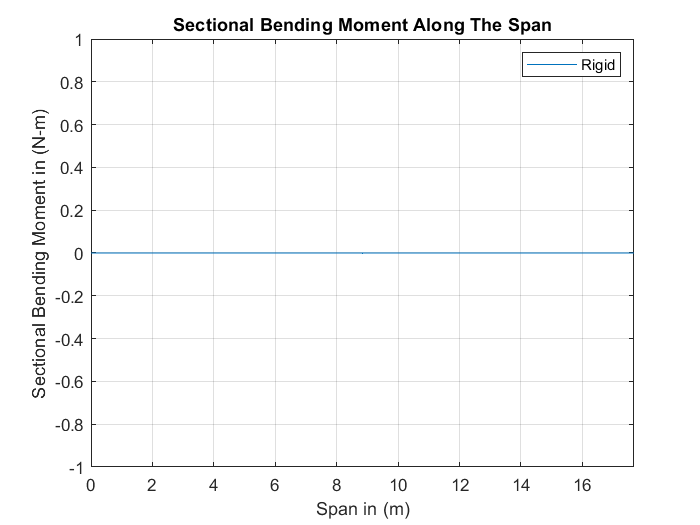

k = 0;
fplot(k, [0 s]);
grid on;
legend('Rigid');
hold off;

ylabel('Sectional Bending Moment in (N-m)');
title('Sectional Bending Moment Along The Span');
xlabel('Span in (m)');

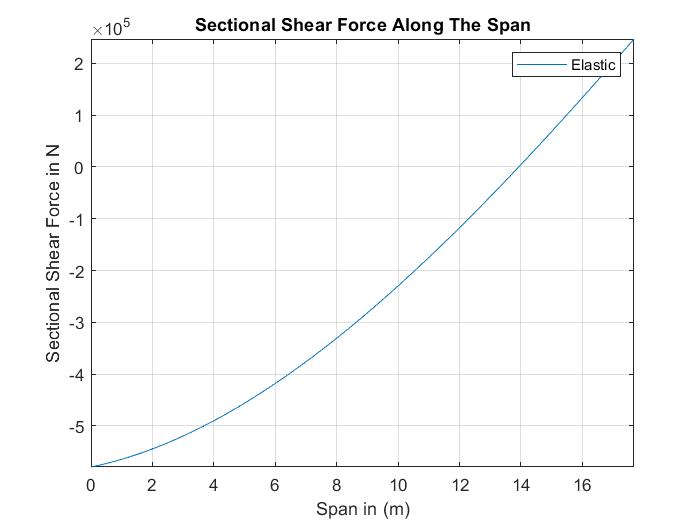

% SpanWise Distribution Of Sectional Shear Force
dw3_dy3 = diff(dw2_dy2, y);
SSF = (EI*(dw3_dy3));
figure(8);
fplot(SSF, [0 s]);
ylabel('Sectional Shear Force in N');
title('Sectional Shear Force Along The Span');
xlabel('Span in (m)');
legend('Elastic');
grid on;
hold off;

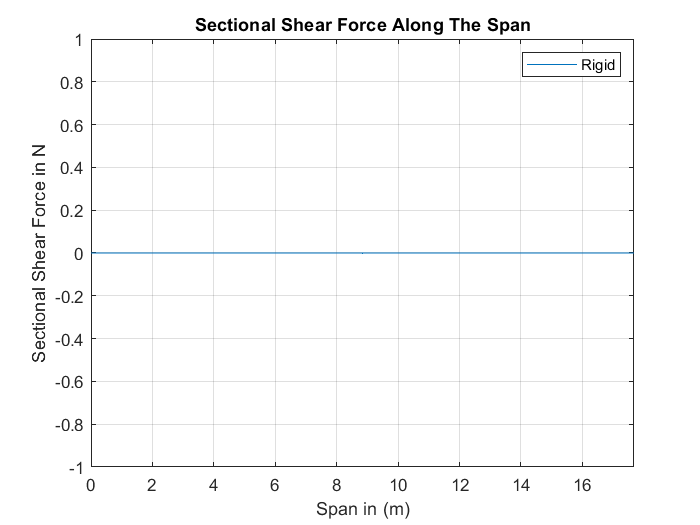

k = 0;
fplot(k, [0 s]);
grid on;
legend('Rigid');
hold off;

ylabel('Sectional Shear Force in N');
title('Sectional Shear Force Along The Span');
xlabel('Span in (m)');

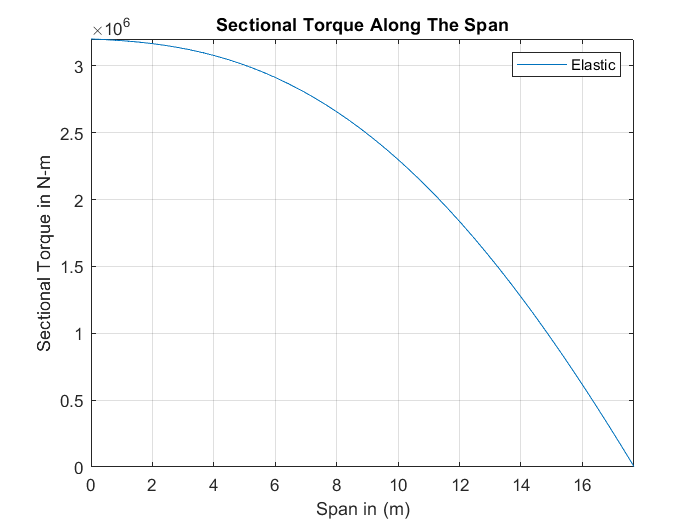

% SpanWise Distribution Of Sectional Torque
dtheta_dy = diff(theta, y);
ST = (GJ*(dtheta_dy));
figure(9);
fplot(ST, [0 s]);
legend('Elastic');
ylabel('Sectional Torque in N-m');
title('Sectional Torque Along The Span');
xlabel('Span in (m)');
grid on;
hold off;

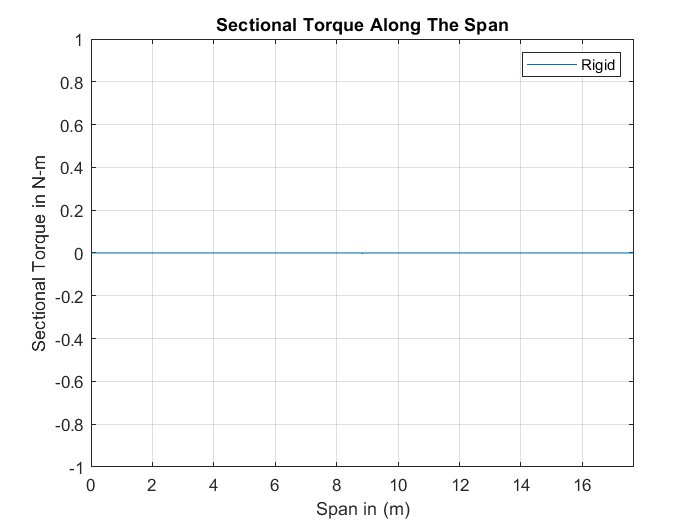

k = 0;
fplot(k, [0 s]);
grid on;

hold off;
legend('Rigid');
ylabel('Sectional Torque in N-m');
title('Sectional Torque Along The Span');
xlabel('Span in (m)');

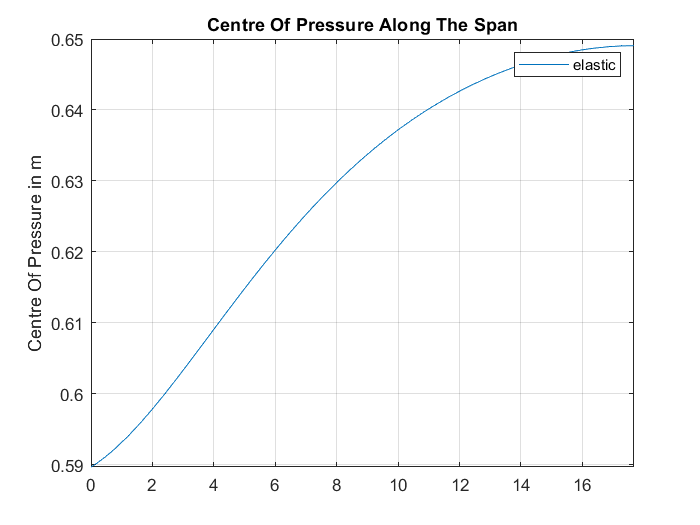

% SpanWise Centre Of Pressure Distribution
COP = ((l*ec)+(Pdyn*(cos(lambda)^2)*(c^2)*cmac0))/l;
COPR = ((lR*ec)+(Pdyn*(cos(lambda)^2)*(c^2)*cmac0))/lR;
figure(10);
fplot(COP, [0 s]);
legend('elastic');
ylabel('Centre Of Pressure in m');
title('Centre Of Pressure Along The Span');
grid on;
hold off;

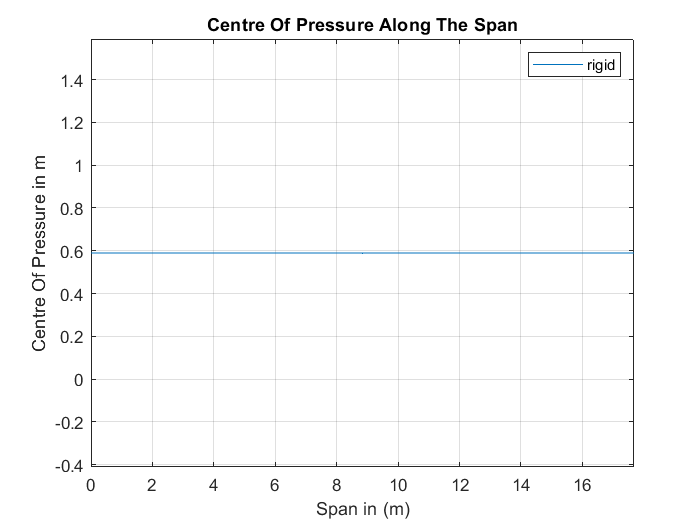

fplot(COPR, [0 s]);
grid on;

hold off;
legend('rigid');
ylabel('Centre Of Pressure in m');
title('Centre Of Pressure Along The Span');
xlabel('Span in (m)');

% Tip Deflection and Tip Twist
y = s;
tip_deflection = subs(w);
tip_deflection = vpa(tip_deflection, 4);
fprintf('Tip Deflection = %f m\n', tip_deflection);

Tip Deflection = 1.350194 m


tip_twist = subs(theta);
tip_twist = vpa(tip_twist, 4);
tip_twist_degrees = (tip_twist*180)/3.1416;
fprintf('Tip Twist = %f degrees\n',tip_twist_degrees);

Tip Twist = 12.733477 degrees


% End Of Program



